# One versus one

This question uses a subset of the iris data - only the sepal widths and sepal lengths for all three classes:

clear all;
load('multiclass.mat', 'examples', 'labels');

This question is about training and visualising a set of Support Vector Machines (SVMs) in a one versus one (OVO) configuration in order to solve a multiclass problem. You should use the whole dataset (without splitting) for training. Note that the dataset has already been z-score stadardised.

Marks are available for:

- An appropriate call to train a set of OVO SVMs on the whole dataset, with default parameters [3 marks]

- An appropriate call to train a *second* set of OVO SVMs on the whole dataset, using the kernel trick with an RBF kernel and a KernelScale of 0.4 [3 marks]

- Extending the `visualiseSVMs()` function to give a helpful visualisation of any 2D model trained by the `fitcecoc()` function (the visualisation should at least include the decision boundaries and the original training data) [8 marks]

- Using the `visualiseSVMs()` function you have developed to produce a visualisation of each of the two sets of SVMs you have trained [2 marks]

- Commenting your code to explain the steps you are taking [4 marks]

[Total: 20 marks]

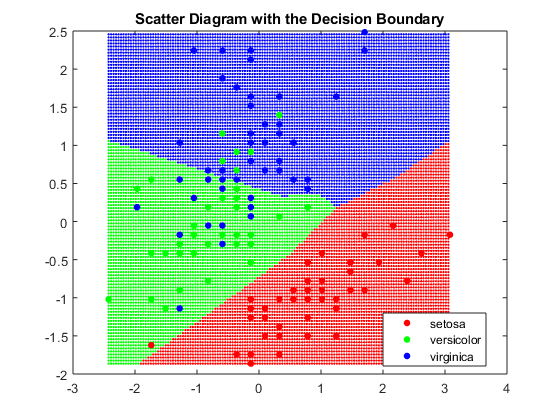

% add as many lines of code as you need below:
%1.
m1 = fitcecoc(examples, labels, 'Coding', 'onevsone');

%2.
t = templateSVM('KernelFunction','rbf','KernelScale', 0.4);

m2 = fitcecoc(examples, labels, 'Coding', 'onevsone', 'Learners', t);
%4.
visualiseSVMs(m1);

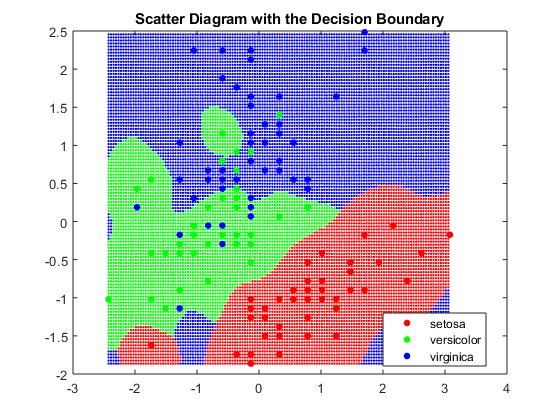

visualiseSVMs(m2);

function visualiseSVMs(m)
%3.
    % Hint: for any model, m, trained with fitcecoc(),
    % you can access the data used to train it with:
d = 0.04;
grid = [];
examples = table2array(m.X);
for i=min(examples(:,1)):d:max(examples(:, 1))
    for j=min(examples(:,2)):d:max(examples(:, 2))
        newRow = [i j];
        grid = [grid; newRow];
    end
end

    % Add as many lines of code as you need below:
    predictions = predict(m,grid); 

figure;

% hexColours = ['#FF0000';'#3CEC3C';'#ffa500';'#0000FF'];
% cmap = hex2rgb(hexColours);
gscatter(grid(:, 1), grid(:, 2), predictions);
hold on;
gscatter(examples(:,1),examples(:,2),m.Y);
% plot(examples(m.IsSupportVector,1),...
%     examples(m.IsSupportVector,2),'ko','MarkerSize',10);


title('Scatter Diagram with the Decision Boundary')
hold off
% legend({'versicolor - testing','virginica - testing','versicolor','virginica','support vectors'}, 'Location','Best')


end